clc
clear
close all
syms d
% Sampling period
Ts = 0.2;
% !!! Task - Specify parameters !!!
w0 = 0.3/Ts;     % frequency utilized in model
n = 7;      % number of additional closed-loop poles
k = 0.16;    % placement of closed-loop poles k=(0.05,0.5)
s = 1.15;    % scaling factor of complex-conjugate poles

% Obtain data
[Fs,ksi,fp,AdB] = mydata_2024(220977);

Transfer function of system Fs(s)

Fs =
 
          1
  -----------------
  s^2 + 6.6 s + 7.6
 
Continuous-time transfer function.
Model Properties
Dumping xi
    0.7300

Frequency of the static disturbance fp [Hz]
    0.9000

Required suppression A [dB]
  -10.8000



% continuous polynomials of system:
b_vect = cell2mat(Fs.num);
a_vect = cell2mat(Fs.den);
% Model
M = tf(w0^2, [1,2*ksi*w0,w0^2]);
% continuous polynomials of model:
gm_vect = cell2mat(M.num);
fm_vect = cell2mat(M.den);
% Discrete-time equivalents
Fs_d = c2d(Fs,Ts)

Fs_d =
 
   0.01317 z + 0.008494
  ----------------------
  z^2 - 1.102 z + 0.2671
 
Sample time: 0.2 seconds
Discrete-time transfer function.
Model Properties


M_d = c2d(M,Ts)

M_d =
 
   0.03881 z + 0.03353
  ----------------------
  z^2 - 1.573 z + 0.6453
 
Sample time: 0.2 seconds
Discrete-time transfer function.
Model Properties


% Get polynomials
b = poly2sym(fliplr(cell2mat(Fs_d.num)),d)

$$b = \frac{1224102134340993\,d^{2}}{144115188075855872}+\frac{7593507994131329\,d}{576460752303423488}$$

a = poly2sym(fliplr(cell2mat(Fs_d.den)),d)

$$a = \frac{4812281785563633\,d^{2}}{18014398509481984}-\frac{4965081279703871\,d}{4503599627370496}+1$$

gm = poly2sym(fliplr(cell2mat(M_d.num)),d)

$$gm = \frac{603983572566899\,d^{2}}{18014398509481984}+\frac{5592710209715209\,d}{144115188075855872}$$

fm = poly2sym(fliplr(cell2mat(M_d.den)),d)

$$fm = \frac{1453144477604343\,d^{2}}{2251799813685248}-\frac{7084120495383857\,d}{4503599627370496}+1$$

## !!! Tasks - Adding dynamics to the system to fulfil requirements !!!

% !!! Task - Add integrator !!!
%hp = 1+2*cos(2*pi*fp*Ts)*d+d^2;
hp = 1-d;
% note: total suppression hp_supp = 1-2*cos(2*pi*fp*Ts)*d+d^2
% note: partial suppression - shift roots outside the unit circle
% !!!! task - achieve partial suppression in frequency fp !!!!
% !!!!!! use defined scaling factor s !!!!!
hp_supp = 1-2*cos(2*pi*fp*Ts)*d+d^2;
root = roots(double(fliplr(coeffs(hp_supp))))*s

root =    0.4896 + 1.0406i
   0.4896 - 1.0406i


hp_supp = expand((d - root(1))*(d - root(2)))

$$hp\_supp = d^{2}-\frac{1102585188829857\,d}{1125899906842624}+\frac{26823486700829335936139986141285}{20282409603651670423947251286016}$$

% Extending hp
hp = simplify(hp*hp_supp);
% Additional closed-loop poles:
x = (1-k*d)^n;

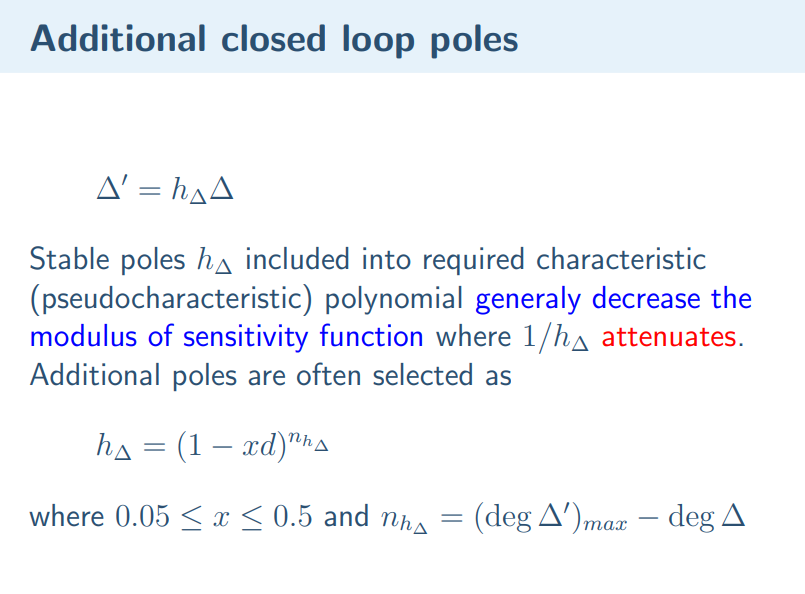

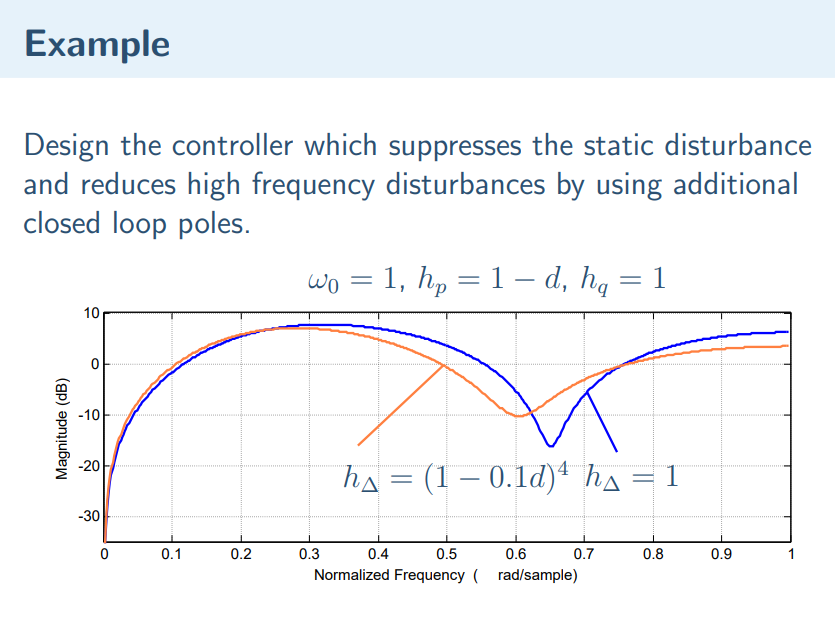

## !!! Tasks - Exact model matching problem !!!

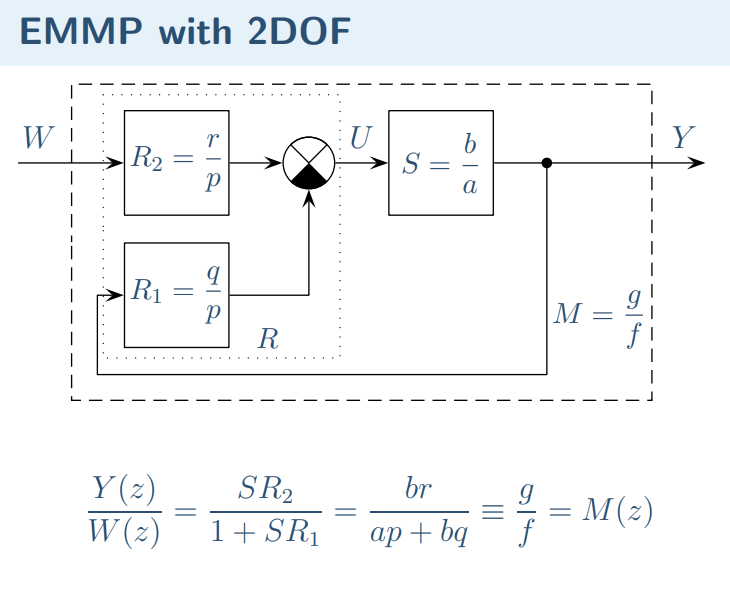

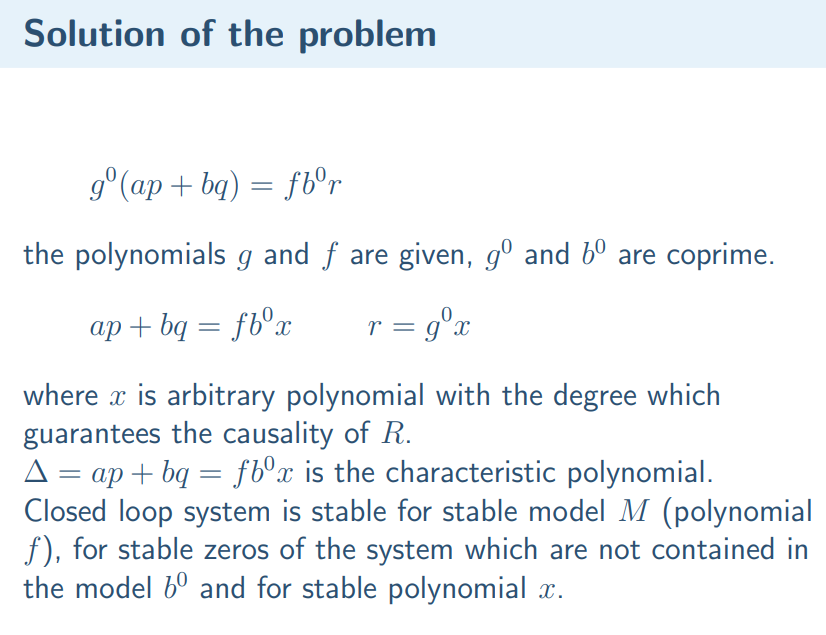

NOTE: b0 and gm0 are coprime

% Extend system's denominator to fulfill all the requirements:
a_ext = a*hp;
[~, ~, b0, g0] = axbyc(b, gm, 0, d)

$$b0 = 4896408537363972\,d+7593507994131329$$

$$g0 = 19327474322140768\,d+22370840838860836$$

c = fm*b0*x

$$c = -{\left(\frac{4\,d}{25}-1\right)}^{7}\,\left(4896408537363972\,d+7593507994131329\right)\,\left(\frac{1453144477604343\,d^{2}}{2251799813685248}-\frac{7084120495383857\,d}{4503599627370496}+1\right)$$

% !!! task - design EMMP controller - use axminbyc !!!!
[p,q] = axminbyc(a_ext,b,c,d);
r = simplify(g0 * x)

$$r = -{\left(\frac{4\,d}{25}-1\right)}^{7}\,\left(19327474322140768\,d+22370840838860836\right)$$

% Expand p with additional dynamics (integrator, disturbance suppresion)
p = p*hp;

## !!! Tasks - RST controller

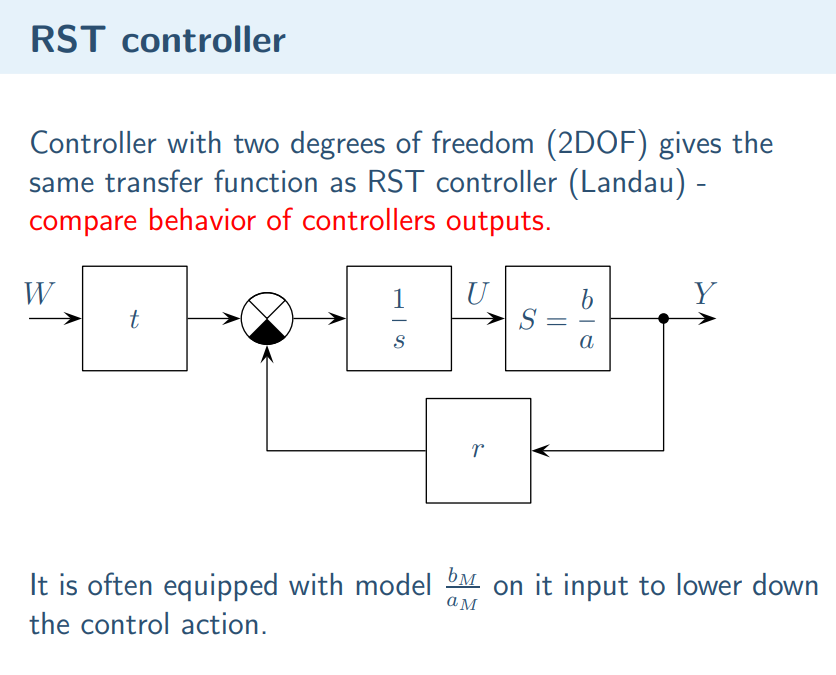

% !!! Task - transfer 2DOF controller to RST form p,q,r - > r,s,t !!!
t = r;
s = p;
r = q;
% Creating vectors:
t_vect = fliplr(sym2poly(t));
s_vect = fliplr(sym2poly(s));
r_vect = fliplr(sym2poly(r));


## Plot characteristics

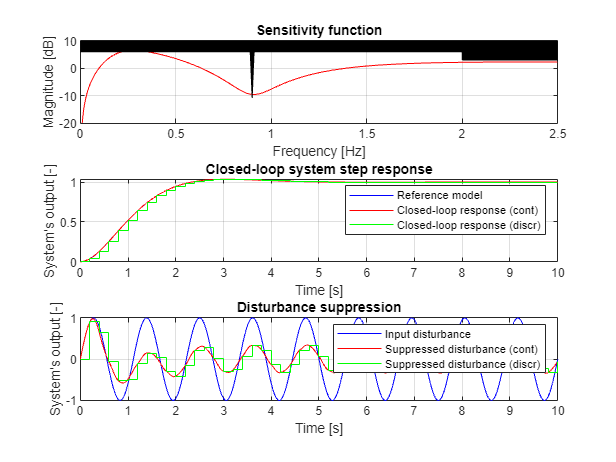

% Sensitivity function:
Syv = simplify((a*p)/(a*p+b*q));
[Syv_num,Syv_den] = numden(Syv);
Syv_num = fliplr(sym2poly(Syv_num));
Syv_den = fliplr(sym2poly(Syv_den));
Syv_num = Syv_num./Syv_den(1);
Syv_den = Syv_den./Syv_den(1);
[Syv_vect,f_vect] = freqz(Syv_num,Syv_den,1250,1/Ts);
Syv_vect = 20*log10(abs(Syv_vect));

% Characteristics form Simulink model
out = sim("model.mdl");
stepresp_cont = out.stepresp_cont;
stepresp_disc = out.stepresp_disc;
distsupp_cont = out.distsupp_cont;
distsupp_disc = out.distsupp_disc;

% Plots
figure
% Sensitivity function
subplot(3,1,1)
plot(f_vect,Syv_vect,'r')
title("Sensitivity function")
xlabel("Frequency [Hz]")
ylabel("Magnitude [dB]")
xlim([0,2.5]);
ylim([-20,10]);
grid on
hold on
area([0 fp-0.01 fp fp+0.01 2 2 2.5],[6 6 AdB 6 6 3 3],10,'FaceColor','k',"EdgeColor",'k')
% Step response and comparison with model
subplot(3,1,2)
plot(stepresp_cont.Time,stepresp_cont.Data(:,1),'b')
hold on
plot(stepresp_cont.Time,stepresp_cont.Data(:,2), 'r')
stairs(stepresp_disc.Time,stepresp_disc.Data(:,:), 'g')
title("Closed-loop system step response")
legend("Reference model", "Closed-loop response (cont)", "Closed-loop response (discr)")
xlabel("Time [s]")
ylabel("System's output [-]")
grid on
% Disturbance suppression
subplot(3,1,3)
plot(distsupp_cont.Time,distsupp_cont.Data(:,1),'b')
hold on
plot(distsupp_cont.Time,distsupp_cont.Data(:,2), 'r')
stairs(distsupp_disc.Time,distsupp_disc.Data(:,:), 'g')
title(strcat("Disturbance suppression"))
legend("Input disturbance", "Suppressed disturbance (cont)", "Suppressed disturbance (discr)")
xlabel("Time [s]")
ylabel("System's output [-]")
grid on